%基于8项经济指标的中国31省市自治区的因子分析（最大似然解，提取2因子）
clear                                                    %清理内存
regions2004                                              %将保存的数据导入内存
X=zscore(data);                                          %原始数据集体标准化
[Lambda,Psi,T,Stats,F]=factoran(X,2,'Score','wls');      %最大似然求解

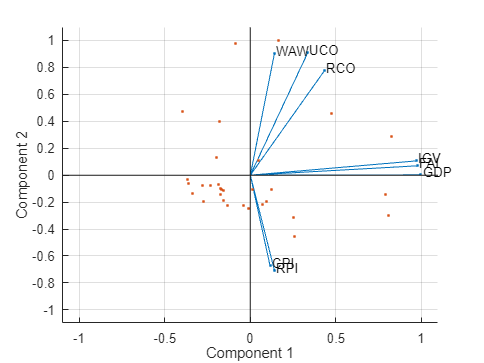

Comm=1-Psi;                                              %计算公因子方差
figure
biplot(Lambda,'scores',F(:,1:2),'varlabels', varname);   %绘制旋转后载荷-得分二重散点图